# Final Report: Pitch-Rate Tracking CAS of Exam 2 Airplane to Meet Certain Specifications

## Step 1: Develop a Short Period Approximation

First and foremost, our full state space model of our exam 2 airplane can be shown by the following:

x_dot = A*x + B*u

y        = C*x + D*u

u is input. columns: [thrust,  elevator]

x contains the states [velocity; alpha (angle of attack); theta (pitch); q (pitch-rate)]

x_dot contains the derivative of the states

y contains the output

A,B,C,and D are matricies as shown below:

% State Space Model (full):
A_full = [-1.1823396e-02   1.8995314e+01  -3.2170000e+01   0.0000000e+00;   
          -2.5712273e-04  -1.2608310e+00   0.0000000e+00   1.0000000e+00;  
           0.0000000e+00   0.0000000e+00   0.0000000e+00   1.0000000e+00;   
           4.5453755e-05  -3.1046195e+00   0.0000000e+00  -1.0595314e+00]

A_full =    -0.0118   18.9953  -32.1700         0
   -0.0003   -1.2608         0    1.0000
         0         0         0    1.0000
    0.0000   -3.1046         0   -1.0595



B_full = [8.1995801e+00   0.0000000e+00;
         -1.6596517e-04   0.0000000e+00;
          0.0000000e+00   0.0000000e+00;
          2.0047958e-02  -4.4032476e-02]

B_full =     8.1996         0
   -0.0002         0
         0         0
    0.0200   -0.0440



C_full = [1 0      0      0      ;
          0 180/pi 0      0      ;
          0 0      180/pi 0      ;
          0 0      0      180/pi]

C_full =     1.0000         0         0         0
         0   57.2958         0         0
         0         0   57.2958         0
         0         0         0   57.2958



D_full = zeros(4,2)

D_full =      0     0
     0     0
     0     0
     0     0


Because alpha and pitch rate are the main contributors to the short period mode of the aircraft, they can be extracted from the full model matricies to make a short period approximation:

% State Space Model (short period approximation)
A_sp = A_full([2,4],[2 4])

A_sp =    -1.2608    1.0000
   -3.1046   -1.0595


B_sp = B_full([2 4],2)

B_sp =          0
   -0.0440


C_sp = C_full([2,4],[2 4])

C_sp =    57.2958         0
         0   57.2958


D_sp = D_full([2 4],2)

D_sp =      0
     0


We can ensure this is accurate by seeing how the eigenvalues of the short period A matrix are nearly identical to short period eigen values of the full model A matrix:

A_full_eig = eig(A_full)

A_full_eig =   -1.1612 + 1.7594i
  -1.1612 - 1.7594i
  -0.0049 + 0.0785i
  -0.0049 - 0.0785i


A_sp_eig = eig(A_sp)

A_sp_eig =   -1.1602 + 1.7591i
  -1.1602 - 1.7591i


## Step 2: Determine Alpha Gain, Compensator Zero, and Pitch-Rate Gain to meet the Short Period Specs

#### Include Additonal Hardware

First and foremost, additional hardware was inlcuded. The entire system of the aircraft is not just the plant i.e. our original matricies. We must incorporate the hardware for 

1. an angle-of-attack (AoA) sensor, along with a filter with transfer function 10/(s+10)

2. a pure pitch-rate sensor

3. actuator motor with transfer function 20.2/(s+20.2)

By making the state space of these transfer functions and then using 'series()' command in matlab, we can incorporarte these pieces of hardware into the existing plant state space to create a new state space. 

We now have new state space matricies that represent actuator + plant + alpha filter:

% simulate short period approximation

% x_dot = A*x + B*u
% y     = C*x + D*u
A = A_sp;                 % x = [alpha; q]
B = B_sp;                 % u = elevator_input
C = C_sp;                 % y = [alpha; q]
D = D_sp;                 % r does not impact q or alpha directly

Plant = ss(A,B,C,D);                                  % ss for plane only i.e. rigid body
[Planttfnum,Planttfden] = ss2tf(A,B,C,D);
Actuator = ss(-20.2, 20.2, -1, 0);                    % ss for actuator motor (with sign change)
[Actuatortfnum,Actuatortfden] = ss2tf(-20.2, 20.2, -1, 0);
AlphaFilter = ss(-10,[10 0],[1; 0],[0 0; 0 1]);       % ss for alpha filter | 2 input 2 output version of tf(10,[1,10])
[AlphaFiltertfnum,Alphafiltertfden] = ss2tf(-10,[10 0],[1; 0],[0 0; 0 1],1);
[Plane] = series(series(Actuator,Plant),AlphaFilter); % Actuator + Plant + AlphaFilter
[AA,BB,CC,DD] = ssdata(Plane)                         % extract ss matricies

AA =   -10.0000  572.9578         0         0
         0   -1.2608    1.0000         0
         0   -3.1046   -1.0595    0.0440
         0         0         0  -20.2000


BB =          0
         0
         0
   20.2000


CC =     1.0000         0         0         0
         0         0   57.2958         0


DD =      0
     0


#### Implement Gains

Now, the alpha gain (ka), compensator zero i.e. integrator gain (ki), and pitch rate gain (kp) must be incorporated.

For inital values of ka, ki, and kp, arbitrary guesses were made, in this case 0.02, 3, and 0.5 respectively.

The first one to focus on would be ka. We can implement it by closing the alpha loop of our control system. 

This is done by multipling our 'CC' matrix by our ka vector [ka 0] (ka only affects alpha, not q), and then by our 'BB' matrix. This result is then subtracted from our previous matrix 'AA' to create a new A matrix.

We now have a new state space. The only change is to the 'AA' matrix, now 'AAcl':

% parameters we set
params = [1.0603 3.5662 1.8422];
ka = params(1); % a = alpha | A, AA, AAA = ss A matrix
ki = params(2);
kp = params(3);


AAcl = AA - BB*[ka 0]*CC                           % Implement k_a (alpha gain)

AAcl =   -10.0000  572.9578         0         0
         0   -1.2608    1.0000         0
         0   -3.1046   -1.0595    0.0440
  -21.4181         0         0  -20.2000


q_u1_ss = ss(AAcl,BB,CC,DD);                          % q/u1 ss
[q_u1_num,q_u1_den] = ss2tf(AAcl,BB,CC(2,:),0);
q_u1_tf = tf(q_u1_num,q_u1_den);                      % q/u1 tf

Next, ki can be implemented by combining the integrator state space (its B matrix contains our ki value) with the state space we just got after implementing ka.

The integrator state space: 

Integrator = ss(0,ki,1,1)                            % ss for integrator control

Integrator =
 
  A = 
       x1
   x1   0
 
  B = 
          u1
   x1  3.566
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   1
 
Continuous-time state-space model.



New state space after combining the integrator state space with our previous state space:

q_r_nokp= series(Integrator,q_u1_ss);                 % x = [alpha_filter alpha q elevator I] 
[AAA,BBB,CCC,DDD]= ssdata(q_r_nokp)                  % extract ss matricies

AAA =   -10.0000  572.9578         0         0         0
         0   -1.2608    1.0000         0         0
         0   -3.1046   -1.0595    0.0440         0
  -21.4181         0         0  -20.2000   20.2000
         0         0         0         0         0


BBB =          0
         0
         0
   20.2000
    3.5662


CCC =     1.0000         0         0         0         0
         0         0   57.2958         0         0


DDD =      0
     0


Finally, kp can be implemented in a similar way as ka was. However, only the sole value of kp is needed as we will mulitiply it only by the second row of 'CCC' which represents pitch rate. Then again, multplied by our current B matrix and subtracted from our current A matrix makes a new A matrix. 

This is our final state space that relates input to pitch rate and alpha (first row of C matrix is for alpha, second row is for pitch rate):


AAAcl = AAA - BBB*kp*CCC(2,:);                       % Implement kp (proportional controller gain)
q_r_ss = ss(AAAcl,kp*BBB,CCC(2,:),0);                 % q/r   ss
a_r_ss = ss(AAAcl,kp*BBB,CCC(1,:),0);                 % a/r   ss
aq_r_ss = ss(AAAcl,kp*BBB,CCC,DDD);                   % a&q/r ss
[aq_r_ss_A,aq_r_ss_B,aq_r_ss_C,aq_r_ss_D] = ssdata(aq_r_ss)  

aq_r_ss_A = 1.0e+03 *

   -0.0100    0.5730         0         0         0
         0   -0.0013    0.0010         0         0
         0   -0.0031   -0.0011    0.0000         0
   -0.0214         0   -2.1321   -0.0202    0.0202
         0         0   -0.3764         0         0


aq_r_ss_B =          0
         0
         0
   37.2124
    6.5697


aq_r_ss_C =     1.0000         0         0         0         0
         0         0   57.2958         0         0


aq_r_ss_D =      0
     0



[q_r_num,q_r_den] = ss2tf(AAAcl,kp*BBB,CCC(2,:),0);
q_r_tf = tf(q_r_num,q_r_den)                         % q/r tf

q_r_tf =
 
           93.88 s^3 + 1392 s^2 + 4954 s + 4221
  ------------------------------------------------------
  s^5 + 32.52 s^4 + 370.4 s^3 + 1995 s^2 + 6391 s + 4221
 
Continuous-time transfer function.



[a_r_num,a_r_den] = ss2tf(AAAcl,kp*BBB,CCC(1,:),0);
a_r_tf = tf(a_r_num,a_r_den)                        % a/r tf

a_r_tf =
 
                      938.8 s + 3348
  ------------------------------------------------------
  s^5 + 32.52 s^4 + 370.4 s^3 + 1995 s^2 + 6391 s + 4221
 
Continuous-time transfer function.



#### Root Locus

The root locus before and after the PI zero was implemented can be seen below

By adding the zero, we can ensure that the lowest kp values will create the lowest osciallatory fequency system.

Additionally, it also drastically decreases the osciallation growth rate as kp increases.

Lastly, it creates a general trend as kp increaes that reduces the damping ratio, meaning that low values of kp will be appropriate for our design.

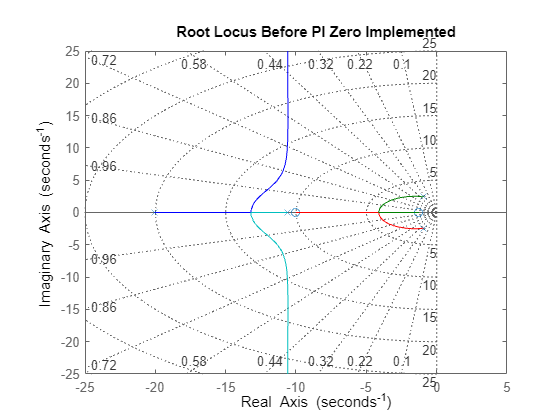

% compare root locus before and after zero (i.e. PI contoller) added 
k_lin= linspace(0,0.9,1000);

rlocus(AAcl,BB(:,1),CC(2,:),DD(1));
title("Root Locus Before PI Zero Implemented")
grid on

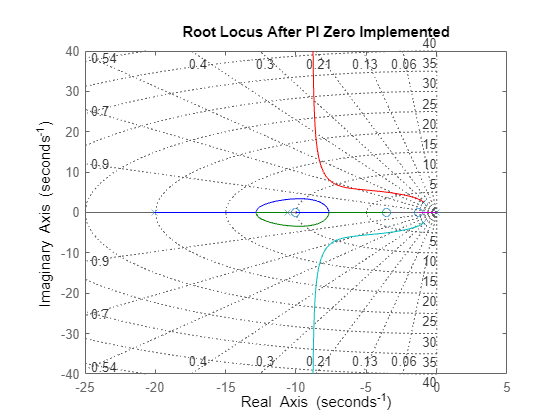


rlocus(AAA,BBB,CCC(2,:),DD(1));
title("Root Locus After PI Zero Implemented")
grid on

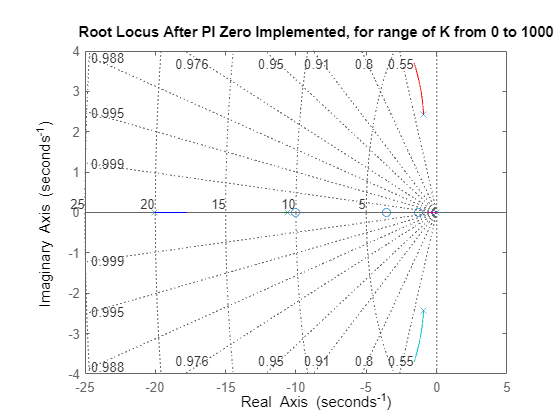

rlocus(AAA,BBB,CCC(2,:),DD(1),k_lin);
title("Root Locus After PI Zero Implemented, for range of K from 0 to 1000")
grid on

#### Frequency, Damping Ratio

Next we calculated the Frequency and Damping Ratio of our short period approximation system. 

The frequency is the largest imaginary part of our eigen values of out final state space A matrix

The natural frequncy is the square root of the frequency squared, and its corresponding real part squared. 

i.e. freq_nat = sqrt(corresponding_real^2 + largest_imag^2)

i.e. magnitude of the distance from the origin to the pole.

The damping ratio is the negative of the corresponing real part divided by the natural frequency. 

By doing this, we got values of:

[z,p,k] = ss2zp(AAAcl,BBB,CCC(2,:),0);

pimags = imag(p);
largest_imag = max(pimags);
corresponding_real = real(p(imag(p)==largest_imag));

freq = largest_imag

freq = 4.6343

freq_nat = sqrt(corresponding_real^2 + largest_imag^2);
damping_ratio = -corresponding_real/freq_nat

damping_ratio = 0.5139

We attemped to achieve the suggested values of a frequncy of 5.80 and damping ratio of 0.70. 

We did this by placing all our previous work in a function and adding the following snippet to the end which shows how far we are from the suggested values. 

frequency_err = (frequency - 5.80)^2;

damping_ratio_err = (damping_ratio - 0.70)^2;

err = freq_err + damping_ratio_err;

By passing our gain parameters into this funciton and returning the error, this mimics linear regression to solve for the lowest error in our function. MATLAB's 'fminsearch()' can be used on this function to recursively find the lowest error, i.e. values of our 3 gains that bring the frequency and damping ratio as close to 5.8 and 0.70 as possible. 

They were found as follows:

`Optimal ka: 1.060294`

`Optimal ki: 3.566154`

`Optimal kp: 3.195926 (later adjusted to 1.8422 manually, see note below)`

Note: When using these values in our Simulink simiulation in the next section, elevator response surpassed the 2 degrees max, so kp was manually adjusted to correct for this.

## Step 3: Plotting Response With Simulink

A block diagram of the entire short period approximaton system was created.

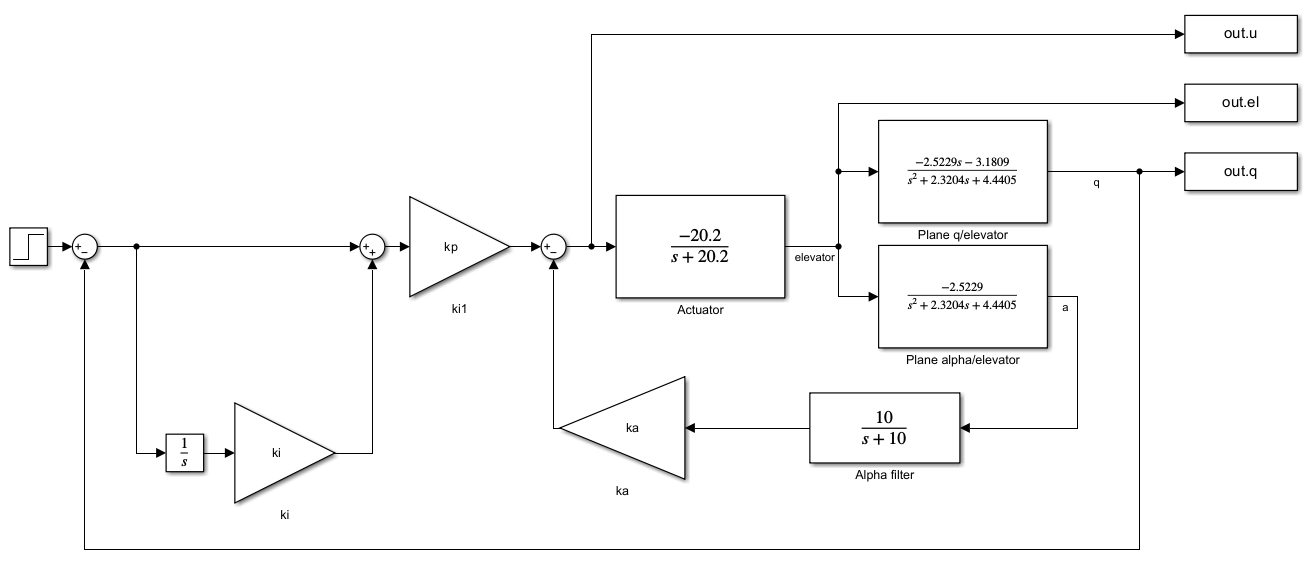

In order to simply the simulink model, we decided to convert our state spaces from our matlab code into transfer functions (using 'ss2tf()'). This required 2 transfer funcitons so that we can have an output of alpha and q.

The pitch rate and elevator response can be easily plotted now because in simulink, the singal can be easily pulled from any point in the system.

This can be seen in the block diagram above where the u signal that goes to our motor, and elevator response after the actuator motor, are both collected as output.

A maltab script was written to run the simulation and plot the output of the responses for easy modification of the control parameters. After kp was manually adjuted to bring the maximum allowable elevator deflection (from its equilibrium value) down to below 2 degrees, the following plots were generated:

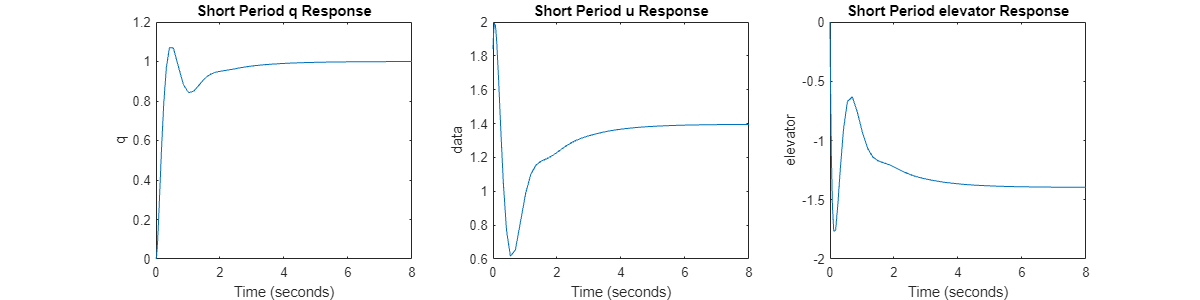

sp = sim('letsgosim');

figure('Position', [0 0 1200 300]); 
subplot(1, 3, 1);
plot(sp.q);
title("Short Period q Response");

subplot(1, 3, 2);
plot(sp.u);
title("Short Period u Response");

subplot(1, 3, 3);
plot(sp.el);
title("Short Period elevator Response");

We decided to record the signal before the actuator as well to show that the u input to the plant is not actually the elevator and the sign change in our actuator transfer function is necessary to ensure the elevator responds in the correct direction. 

Note: The q response plot can still be generated from the matlab code before using Simulink. That plot can be seen below and from that plot we can confirm the setteling time is less than 5 seconds:

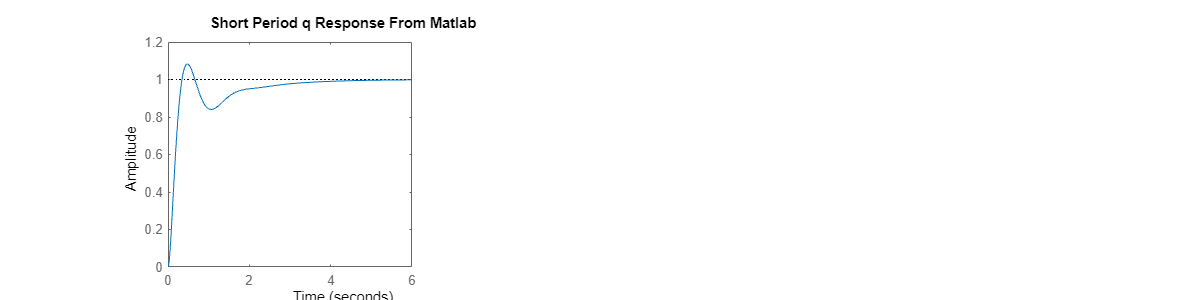

figure('Position', [0 0 1200 300]); 
subplot(1, 3, 1);
step(q_r_tf)
title("Short Period q Response From Matlab")

info = stepinfo(q_r_tf);
settling_time = info.SettlingTime

settling_time = 3.1477

## Step 4: Full Model

A block diagram of the entire full model of the system was created.

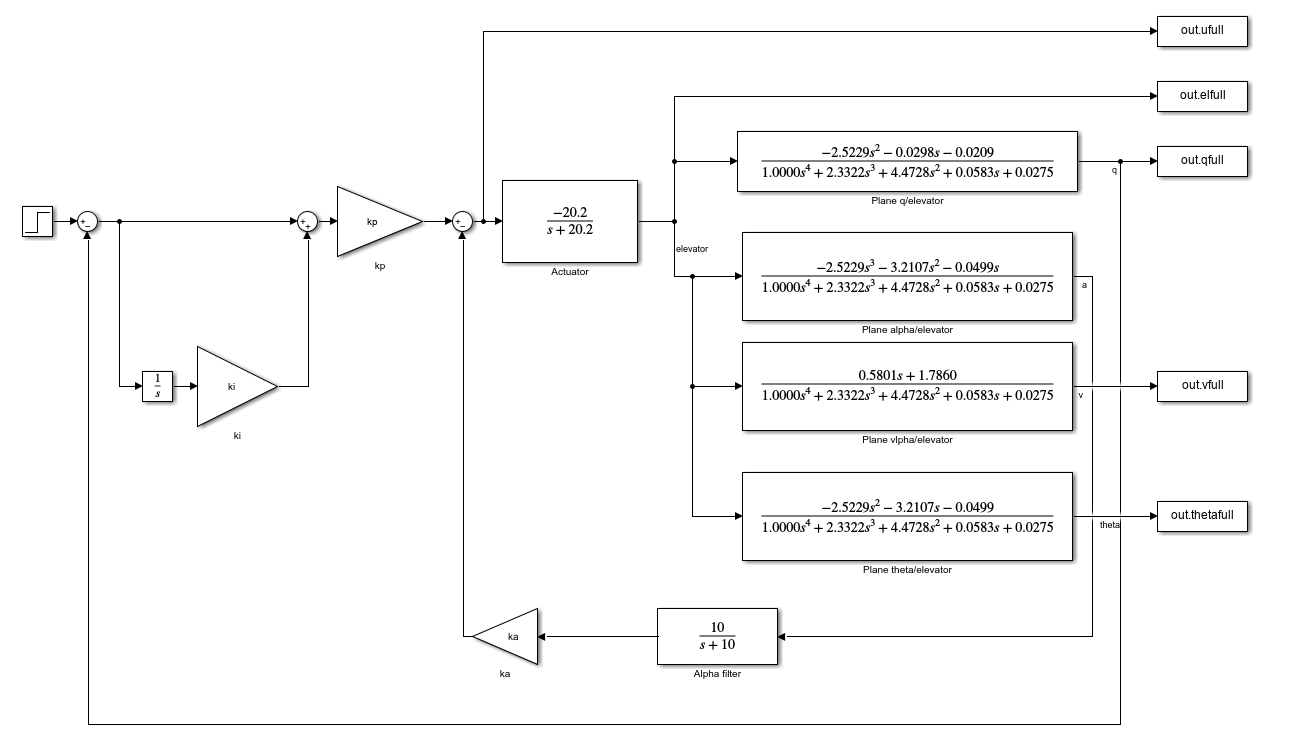

As we were using transfer funciton and not state space models in simulink, 2 more transfer funcitons needed to be added to output the 2 additional states, the velocity and pitch of the airplane.

Below are plots for all state responses for the full model system with simulations for both 10 seconds duration and 1000: 

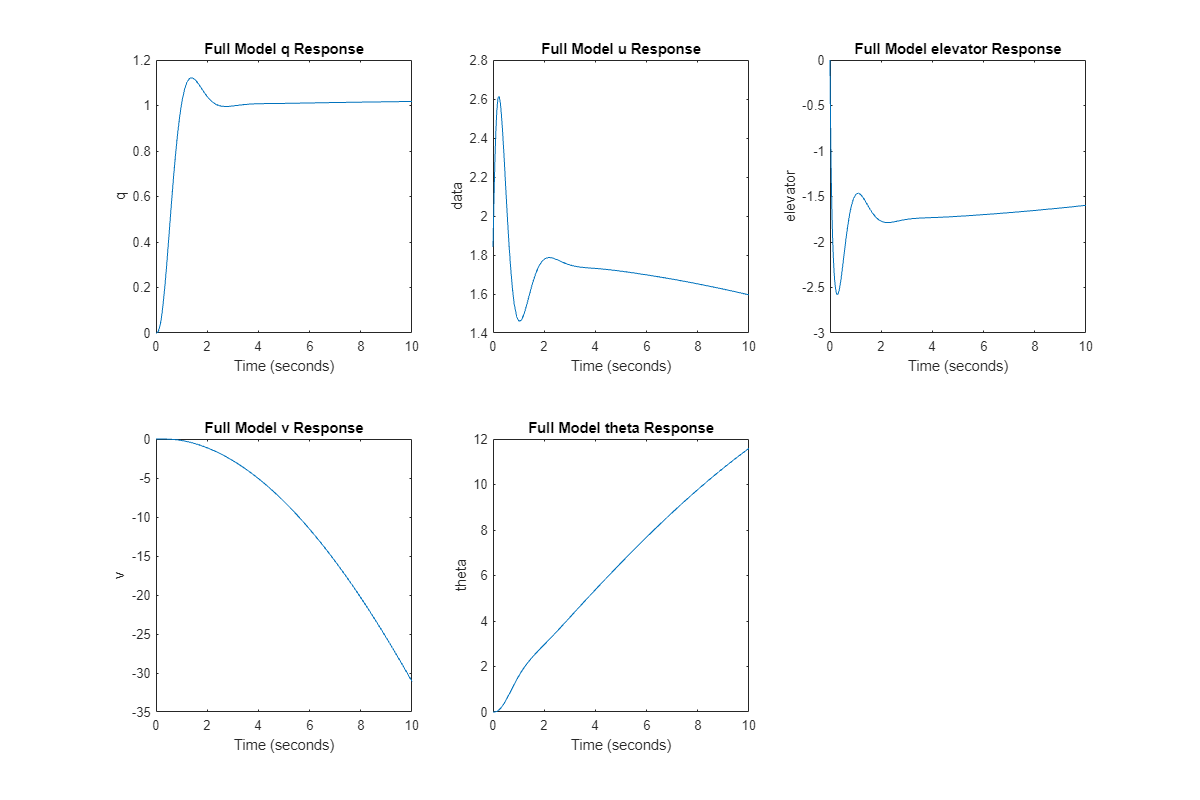

fm = sim('letsgosimfull');
longfm = sim('letsgosimfulllong.slx');

figure('Position', [0 0 1200 800]); 
subplot(2, 3, 1);
plot(fm.qfull);
title("Full Model q Response");
subplot(2, 3, 2);
plot(fm.ufull);
title("Full Model u Response");
subplot(2, 3, 3);
plot(fm.elfull);
title("Full Model elevator Response");
subplot(2, 3, 4);
plot(fm.vfull);
title("Full Model v Response");
subplot(2, 3, 5);
plot(fm.thetafull);
title("Full Model theta Response");

Comparing the elevator response from the 10 second plot of the full model to the short period approximation, it can be seen that the overshoot passes 2 degrees in the full model while it does not for the approximate model, where it is just under 2 degrees. With this information, we can conclude that the approximation may not always be accurate enough to create a control system for the full model, especially if you design the controller to the limit of the specifications. Ta adjust for this, we can add a buffer factor when using the approximate model to design the control values to ensure the full model response is appropriate.

Additionally, it can be seen that the frequency and settling time of the q response from the full model differ slightly from the short period approximate model. In this case the frequency is lower, and the settling time is smaller. When designing a system using approximations, all of this need to be considered, which is why it is important to verify our design with the full model after the values are chosen.

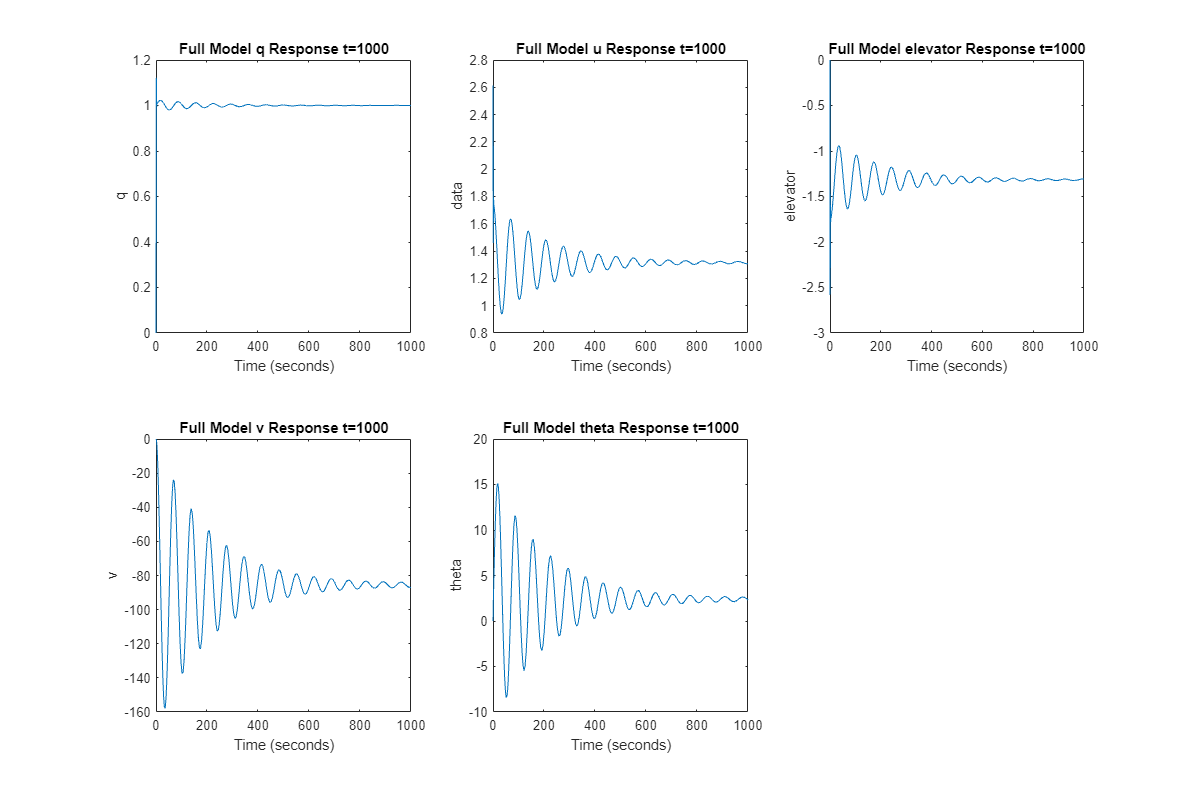

figure('Position', [0 0 1200 800]);
subplot(2, 3, 1);
plot(longfm.qfull);
title("Full Model q Response t=1000");
subplot(2, 3, 2);
plot(longfm.ufull);
title("Full Model u Response t=1000");
subplot(2, 3, 3);
plot(longfm.elfull);
title("Full Model elevator Response t=1000");
subplot(2, 3, 4);
plot(longfm.vfull);
title("Full Model v Response t=1000");
subplot(2, 3, 5);
plot(longfm.thetafull);
title("Full Model theta Response t=1000");